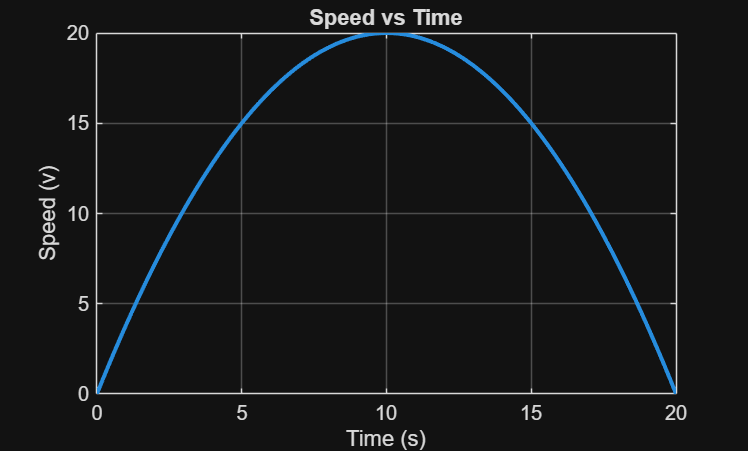

%{
Autonomous Cart Speed Profile (Quadratic + Numerical Change)
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Models a cart over time
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showing speed vs time and acceleration vs time 
MATLAB tools/functions:
    - functions
    - plots
    - tables
%}
% Define time vector and evaluate speed v(t)
t = 0:0.2:20;
v = -0.2 * (t - 10).^2 + 20;

% Plot for speed vs time
figure(1);
plot(t, v, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed (v)');
title('Speed vs Time');
grid on;

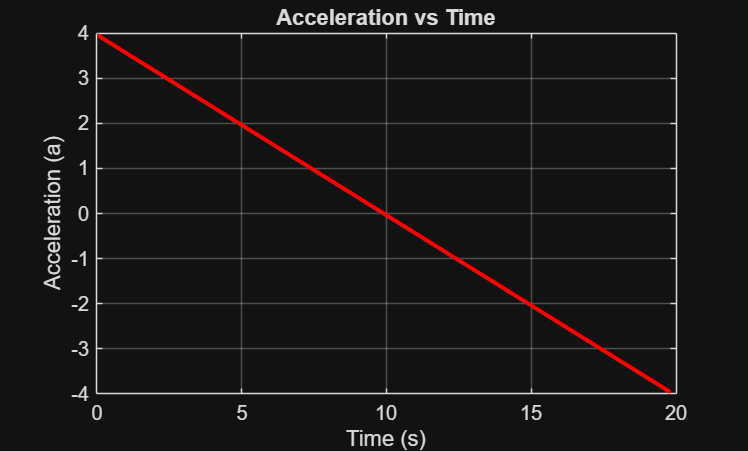


% estimate acceleration a(t)
dv = diff(v);           % Change in speed
dt = diff(t);           % Change in time (0.2)
a = dv ./ dt;           % a = delta_v / delta_t
t_a = t(1:end-1);       % Adjust time vector for diff (length is N-1)

% Plot for acceleration vs time
figure(2);
plot(t_a, a, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Acceleration (a)');
title('Acceleration vs Time');
grid on;

%{
the vertex is when the speed peaks,and a positive acceleration means the
cart is speeding up while a negative acceleration means that the cart is
slowing down.
%}
